# Actividad 5

## Robot 1

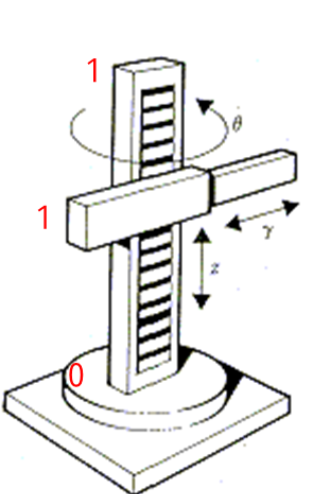

%Limpieza de pantalla
clear all
close all
clc

%Declaración de variables simbólicas
syms th1(t) l1(t) l2(t) l3(t) t

Configuramos el robot, la primera articulación es 0 ya que es antropomoformica y las otras 2 son 1 porque son prismáticas.

%Configuración del robot, 0 para junta rotacional, 1 para junta prismática
RP=[0 1 1];

%Creamos el vector de coordenadas articulares
Q= [th1, l1, l2];
%disp('Coordenadas generalizadas');
%pretty (Q);

%Creamos el vector de velocidades generalizadas
Qp= diff(Q, t);
%disp('Velocidades generalizadas');
%pretty (Qp);
%Número de grado de libertad del robot
GDL= size(RP,2);
GDL_str= num2str(GDL);
% [0 0 1;  %y +90
%  0 1 0;
% -1 0 0];xº

% [1 0 0;  %x +90
%  0 0 1;
%  0 -1 0];


 

%Articulación 1 
%Posición de la articulación 1 respecto a 0
P(:,:,1)= [0; 0; l1];%Porque esta ligeramente levando respecto a mi mundo
%Matriz de rotación en z ya que esta rotando sobre el eje z
R(:,:,1)=[cos(th1),-sin(th1),0;
          sin(th1),cos(th1),0;
          0,0,1];
%Articulación 2 
%Posición de la articulación 2 respecto a 1
P(:,:,2) = [0; 0;l2];
%Matriz de rotación de la junta 2 respecto a 1...necesitamos voltera -90°
%en y para la siguiente configuración
R(:,:,2)=[cos(-90),  0, sin(-90);
           0,        1,    0    ;
          -sin(-90), 0, cos(-90)];
    
%Articulación 3 
%Posición de la articulación 3 respecto a 2 que solo se mueve en z
P(:,:,3)= [0; 0; l3];
%Matriz de rotación de la junta 3 respecto a 2 se queda igual, por eso es
%la identidad
R(:,:,3)=   [1 0 0;
             0 1 0;     
             0 0 1];
%Creamos un vector de ceros
Vector_Zeros= zeros(1, 3);

%Inicializamos las matrices de transformación Homogénea locales
A(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las matrices de transformación Homogénea globales
T(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las posiciones vistas desde el marco de referencia inercial
PO(:,:,GDL)= P(:,:,GDL); 
%Inicializamos las matrices de rotación vistas desde el marco de referencia inercial
RO(:,:,GDL)= R(:,:,GDL); 


for i = 1:GDL
    i_str= num2str(i);
   %disp(strcat('Matriz de Transformación local A', i_str));
    A(:,:,i)=simplify([R(:,:,i) P(:,:,i); Vector_Zeros 1]);
   %pretty (A(:,:,i));

   %Globales
    try
       T(:,:,i)= T(:,:,i-1)*A(:,:,i);
    catch
       T(:,:,i)= A(:,:,i);
    end
    disp(strcat('Matriz de Transformación global T', i_str));
    T(:,:,i)= simplify(T(:,:,i));
    pretty(T(:,:,i))

    RO(:,:,i)= T(1:3,1:3,i);
    PO(:,:,i)= T(1:3,4,i);
    %pretty(RO(:,:,i));
    %pretty(PO(:,:,i));
end

Matriz de Transformación global T1


/ cos(th1(t)), -sin(th1(t)), 0,   0   \
|                                     |
| sin(th1(t)),  cos(th1(t)), 0,   0   |
|                                     |
|      0,            0,      1, l1(t) |
|                                     |
\      0,            0,      0,   1   /



Matriz de Transformación global T2


/   4035888341267763 cos(th1(t))                  4026203041061939 cos(th1(t))                \
| - ----------------------------, -sin(th1(t)), - ----------------------------,       0       |
|         9007199254740992                              4503599627370496                      |
|                                                                                             |
|   4035888341267763 sin(th1(t))                  4026203041061939 sin(th1(t))                |
| - ----------------------------,  cos(th1(t)), - ----------------------------,       0       |
|         9007199254740992                              4503599627370496                      |
|                                                                                             |
|        4026203041061939                               4035888341267763                      |
|        ----------------,              0,            - ----------------,       l1(t) + l2(t) |
|        4503599627370496               

Matriz de Transformación global T3


/   4035888341267763 cos(th1(t))                  4026203041061939 cos(th1(t))     4026203041061939 cos(th1(t)) l3(t)  \
| - ----------------------------, -sin(th1(t)), - ----------------------------,  - ----------------------------------  |
|         9007199254740992                              4503599627370496                    4503599627370496           |
|                                                                                                                      |
|   4035888341267763 sin(th1(t))                  4026203041061939 sin(th1(t))     4026203041061939 sin(th1(t)) l3(t)  |
| - ----------------------------,  cos(th1(t)), - ----------------------------,  - ----------------------------------  |
|         9007199254740992                              4503599627370496                    4503599627370496           |
|                                                                                                                      |
|        4026203041061939       



%Calculamos el jacobiano lineal de forma diferencial
%disp('Jacobiano lineal obtenido de forma diferencial');
%Derivadas parciales de x respecto a th1 y th2
Jv11= functionalDerivative(PO(1,1,GDL), th1);
Jv12= functionalDerivative(PO(1,1,GDL), l1);
Jv13= functionalDerivative(PO(1,1,GDL), l2);
%Derivadas parciales de y respecto a th1 y th2
Jv21= functionalDerivative(PO(2,1,GDL), th1);
Jv22= functionalDerivative(PO(2,1,GDL), l1);
Jv23= functionalDerivative(PO(2,1,GDL), l2);
%Derivadas parciales de z respecto a th1 y th2
Jv31= functionalDerivative(PO(3,1,GDL), th1);
Jv32= functionalDerivative(PO(3,1,GDL), l1);
Jv33= functionalDerivative(PO(3,1,GDL), l2);

%Creamos la matríz del Jacobiano lineal
jv_d=simplify([Jv11 Jv12 Jv13;
              Jv21 Jv22 Jv23;
              Jv31 Jv32 Jv33]);
%pretty(jv_d);


%Calculamos el jacobiano lineal de forma analítica
Jv_a(:,GDL)=PO(:,:,GDL);
Jw_a(:,GDL)=PO(:,:,GDL);

for k= 1:GDL
    if RP(k)==0 
       %Para las juntas de revolución
        try
            Jv_a(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL)-PO(:,:,k-1));
            Jw_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)= cross([0,0,1], PO(:,:,GDL));%Matriz de rotación de 0 con respecto a 0 es la Matriz Identidad, la posición previa tambien será 0
            Jw_a(:,k)=[0,0,1];%Si no hay matriz de rotación previa se obtiene la Matriz identidad
         end
     else
%         %Para las juntas prismáticas
        try
            Jv_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)=[0,0,1];
        end
            Jw_a(:,k)=[0,0,0];
     end
 end    

Jv_a= simplify (Jv_a);
Jw_a= simplify (Jw_a);
%disp('Jacobiano lineal obtenido de forma analítica');
%pretty (Jv_a);
%disp('Jacobiano ángular obtenido de forma analítica');
%pretty (Jw_a);


disp('Velocidad lineal obtenida mediante el Jacobiano lineal');

Velocidad lineal obtenida mediante el Jacobiano lineal


V=simplify (Jv_a*Qp');
disp(V);

$$\begin{array}{l} \left(\begin{array}{c} \frac{4026203041061939\,\bar{\frac{\partial }{\partial t}{\mathrm{th}}_{1}\left(t\right)}\,\sin\left({\mathrm{th}}_{1}\left(t\right)\right)\,l_{3}\left(t\right)}{4503599627370496}-\frac{4026203041061939\,\sigma_{1}\,\cos\left({\mathrm{th}}_{1}\left(t\right)\right)}{4503599627370496}\\ -\frac{4026203041061939\,\sigma_{1}\,\sin\left({\mathrm{th}}_{1}\left(t\right)\right)}{4503599627370496}-\frac{4026203041061939\,\bar{\frac{\partial }{\partial t}{\mathrm{th}}_{1}\left(t\right)}\,\cos\left({\mathrm{th}}_{1}\left(t\right)\right)\,l_{3}\left(t\right)}{4503599627370496}\\ \bar{\frac{\partial }{\partial t}l_{1}\left(t\right)}-\frac{4035888341267763\,\sigma_{1}}{9007199254740992} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\bar{\frac{\partial }{\partial t}l_{2}\left(t\right)} \end{array}$$

disp('Velocidad angular obtenida mediante el Jacobiano angular');

Velocidad angular obtenida mediante el Jacobiano angular


W=simplify (Jw_a*Qp');
disp(W);

$$\left(\begin{array}{c} 0\\ 0\\ \bar{\frac{\partial }{\partial t}{\mathrm{th}}_{1}\left(t\right)} \end{array}\right)$$